# Regelung von Robotern

# Teil 1: Regelung der Lage bzw. von Trajektorien

%bdclose all    % close all Simulink models
close all      % close all figures
clear          % clear all workspace variables
format compact % compact printout 

## Laden des Modell des Roboters ABB IRB 120

[robot,robotdata] = loadrobot('abbIrb120',DataFormat='row',Gravity=[0,0,-9.81]);
%show(robot);

Gelenkkonfiguration in Nullstellung

qhome = homeConfiguration(robot)

qhome =      0     0     0     0     0     0


Transformationsmatrix für Nullstellung

EE = "tool0";
T = robot.getTransform(qhome, EE)

T =     1.0000         0         0    0.3740
         0    1.0000         0         0
         0         0    1.0000    0.6300
         0         0         0    1.0000


## Spezifikation einer Bewegungsaufgabe im Arbeitsraum

### Spezifikationen von Positionen (Bahnpunkte) im Arbeitsraum (Orientierung bleibt konstant)

P0 = T(1:3,4);
P1 = [0.5;0;0.8];
P2 = [0.5;-0.25;0.3];
P3 = [0.5;0.25;0.3];
waypoints = [P0,P1,P2,P3,P1,P0];
numWaypoints = size(waypoints,2);

### Planung einer Trajektorie mit trapezförmigen Geschwindigkeitsprofil zwischen den Bahnpunkten 

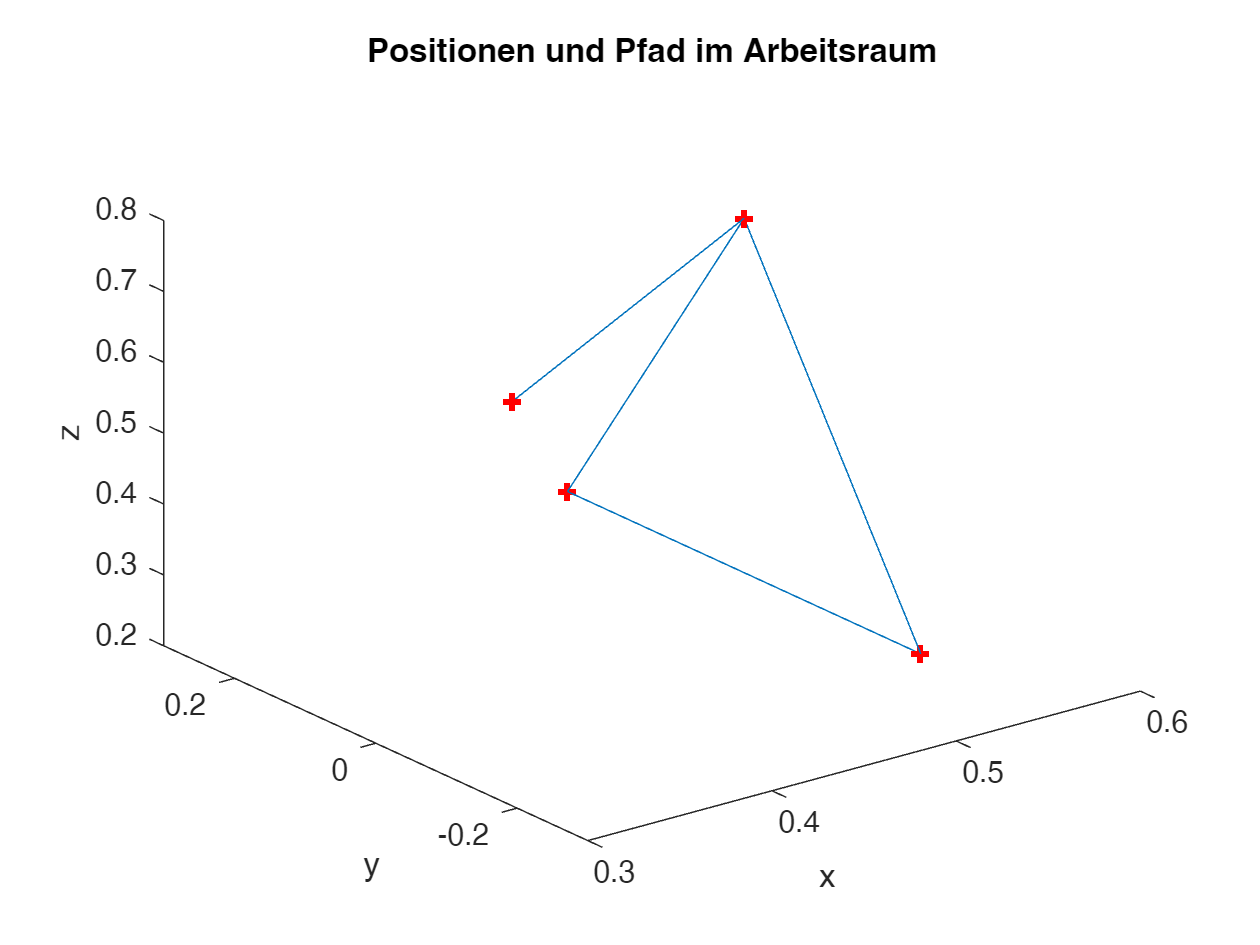

[x,xd,xdd,trajpoints] = trapveltraj(waypoints,500,EndTime=1);

figure;
plot3(x(1,:),x(2,:),x(3,:),'-')
hold on;
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'r+','LineWidth',2)
axis([0.3,0.6,-0.3,0.3,0.2,0.8]);
xlabel('x');
ylabel('y');
zlabel('z');
title('Positionen und Pfad im Arbeitsraum')

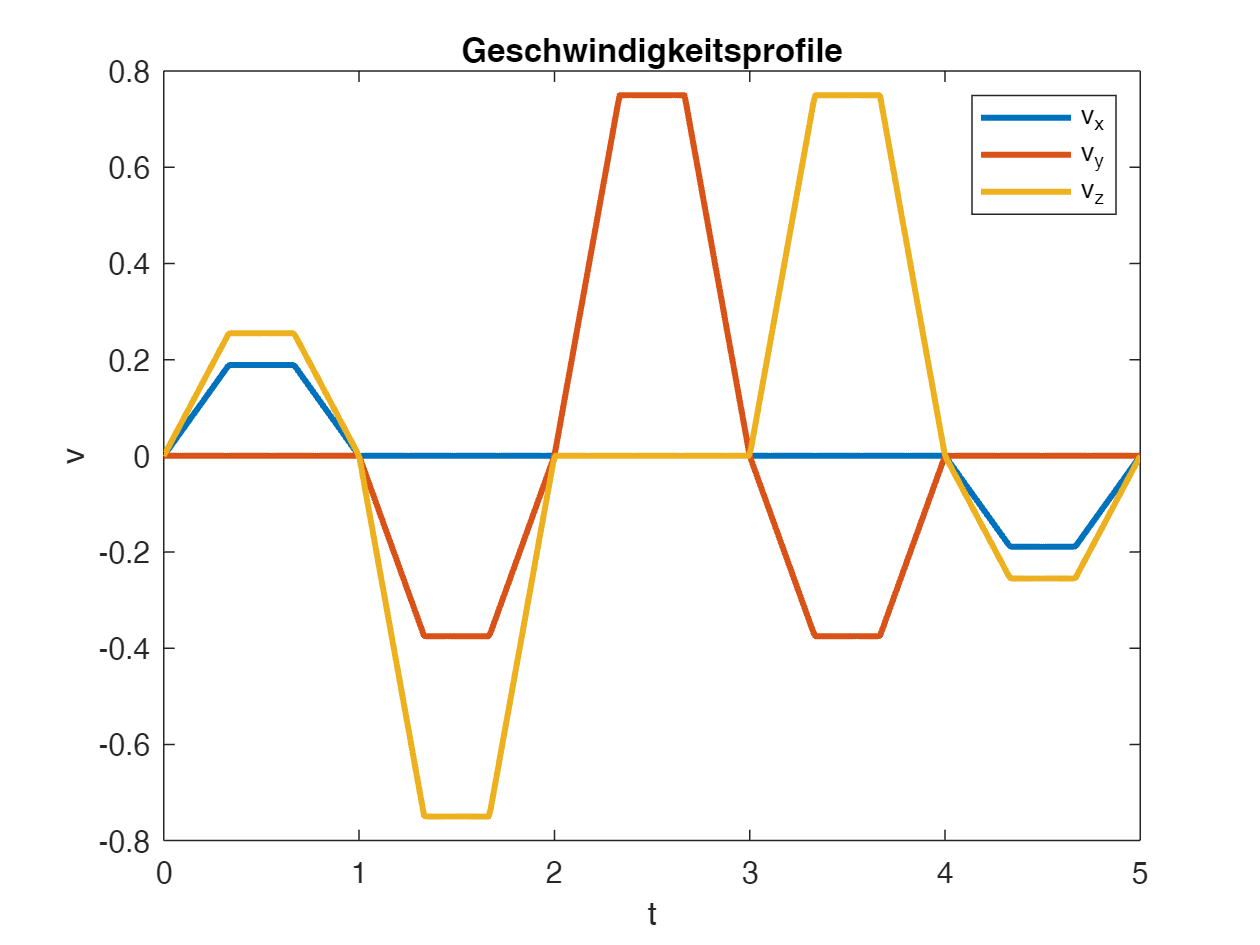

figure;
plot(trajpoints,xd,'LineWidth',2)
xlabel('t');
ylabel('v');
legend('v_x','v_y','v_z')
title('Geschwindigkeitsprofile');

#### Inverse Kinematik

ik = inverseKinematics('RigidBodyTree',robot);
weights = [.1,.1,.1,1,1,1];
T1 = trvec2tform(P1');
C1 = ik(EE,T1,weights,qhome);
T2 = trvec2tform(P2');
C2 = ik(EE,T2,weights,qhome);
T3 = trvec2tform(P3');
C3 = ik(EE,T3,weights,qhome);

#### Trajektorie im Gelenkraum mit trapezförmigen Geschwindigkeitsprofil

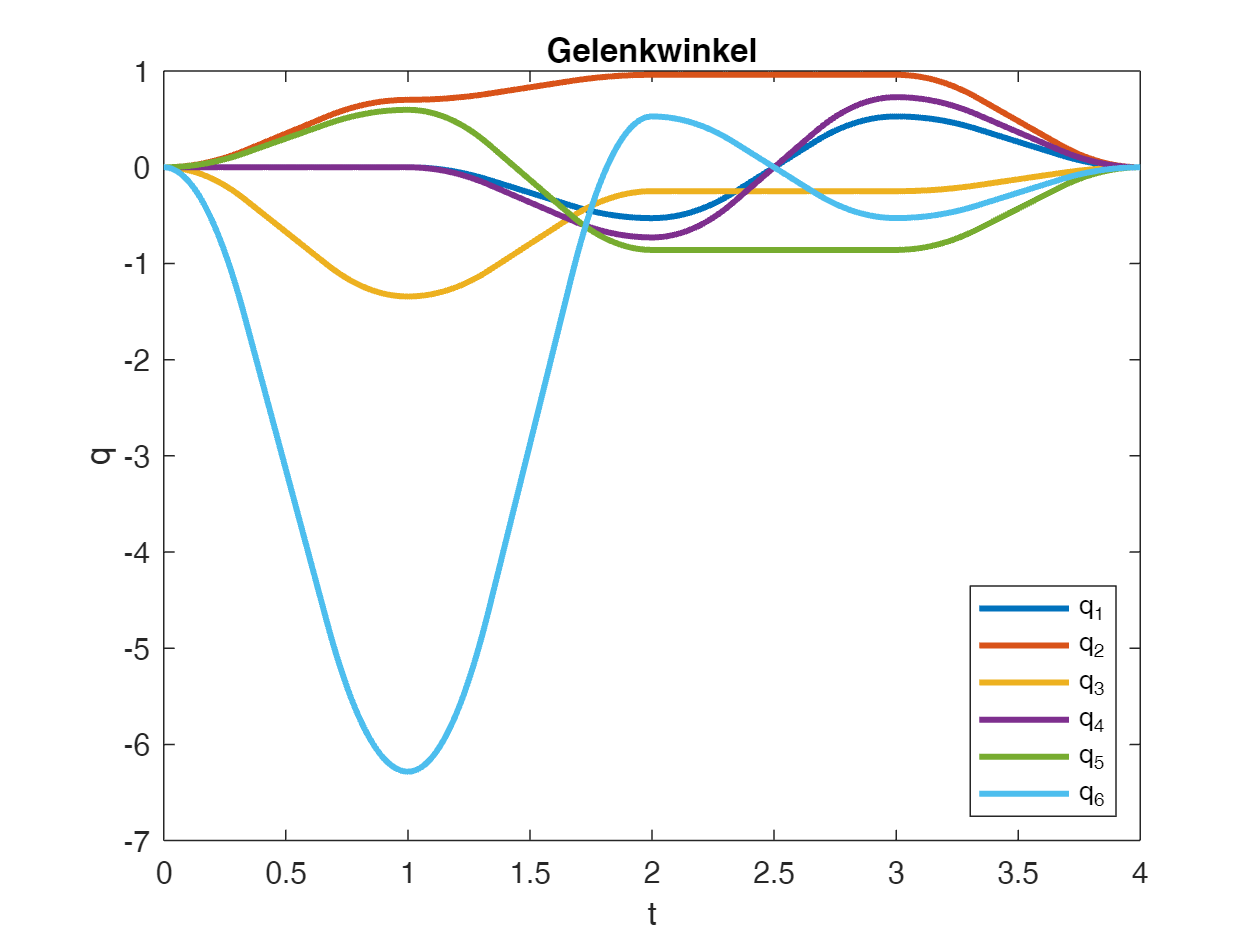

[q,qd,qdd,qtrajpoints] = trapveltraj([qhome',C1',C2',C3',qhome'],500,EndTime=1);
figure;
plot(qtrajpoints,q,'LineWidth',2)
xlabel('t');
ylabel('q');
legend('q_1','q_2','q_3','q_4','q_5','q_6',Location='southeast')
title('Gelenkwinkel');

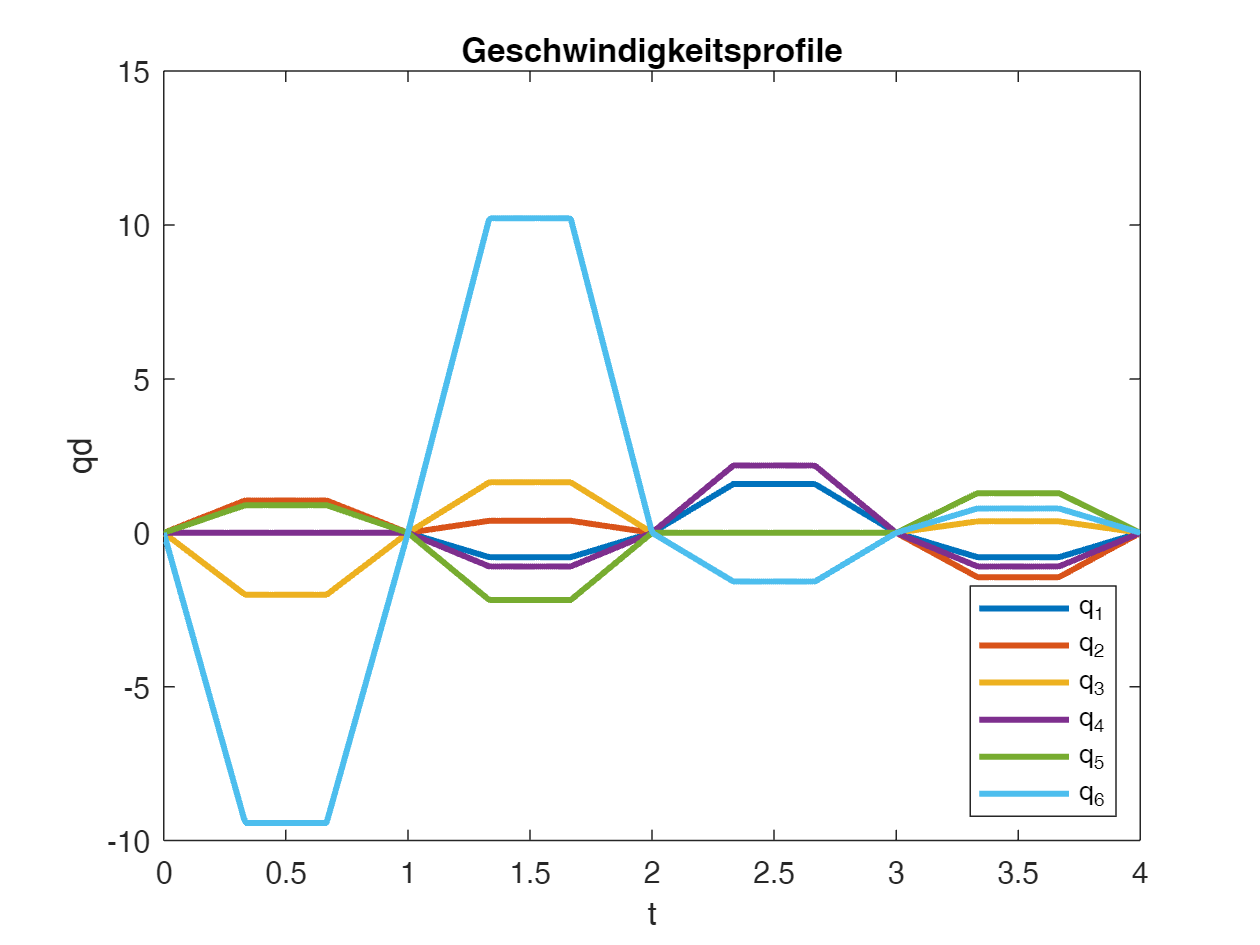

figure;
plot(qtrajpoints,qd,'LineWidth',2)
xlabel('t');
ylabel('qd');
legend('q_1','q_2','q_3','q_4','q_5','q_6',Location='southeast')
title('Geschwindigkeitsprofile');